I = 0.5;
k_I = 0.1867;
k_mI = 0.7801;
k_A = 0.9833;
k_B = 0.8252;
k_mA = 0.4083;
k_1 = 0.3132;
k_m1= 0.5770;
k_2 = 0.2636; %IRREVERSIBLE
k_m2 = 0.1090; 
delta_1 = 0.0697; 
delta_2 = 0.0226;

%set k_mB to some relevant value where you're plotting trajectories 
k_mB = 0.91;

function dydt = nf1(t,y, I, k_I, k_mI, k_A, k_B, k_mA, k_mB, k_1, k_m1, k_2, k_m2, delta_1, delta_2)
% y(1) is a, y(2) is b
% Solve the ODE   (below  x=y(1) and y=y(2))
% I = params(1);
% k_I = params(2);
% k_mI = params(3);
% k_A = params(4);
% k_B = params(5);
% k_mB = params(6);
% k_1 = params(7);
% k_m1= params(8);
% k_2 = params(9); 
% k_m2 = params(10);
% delta_1 = params(11);
% delta_2 = params(12);
% dydt(1) = (k_I*I*(1-y(1)) )./(k_mI + 1 - y(1) );
% dydt(2) =  (k_B*y(2)*(1-y(2)))./(k_mB + 1 - y(2) );

%define da/dt then db/dt
dydt = [ ((k_I*I*(1-y(1)) )./(k_mI + 1 - y(1))) + ((k_A*y(1)*(1-y(1)))./(k_mA + 1 - y(1))) - ((k_2*y(1)* y(2))./(k_m2+ y(1))) - (delta_1*y(1)) ;
    ((k_B*y(2)*(1-y(2)))./(k_mB + 1 - y(2))) + ((k_1*y(1)*(1-y(2)))./(k_m1 + 1 - y(2))) - (delta_2*y(2)) ];
end

aval = 0:.05:1;
bval = 0:.05:1;

%define mesh grid for a and b, specified as ap and bp
[am,bm]=meshgrid(aval,bval);
ap = (k_I*I*(1-am) )./(k_mI + 1 - am );
bp =  (k_B*bm*(1-bm) )./(k_mB + 1 - bm );
sza = sqrt(ap.^2+bp.^2);


tend = 999999;
%[A B] 
%SET BELOW !!!
%unstasble for 0.91: [0.2153, 0.9774]
y0 = [0.2152, 0.9773]

y0 =    0.215200000000000   0.977300000000000


tspan = [0 tend]

tspan =            0      999999


[tx,exsolx] = ode45(@(t,y) nf1(t, y, I, k_I, k_mI, k_A, k_B, k_mA, k_mB, k_1, k_m1, k_2, k_m2, delta_1, delta_2), tspan, y0);

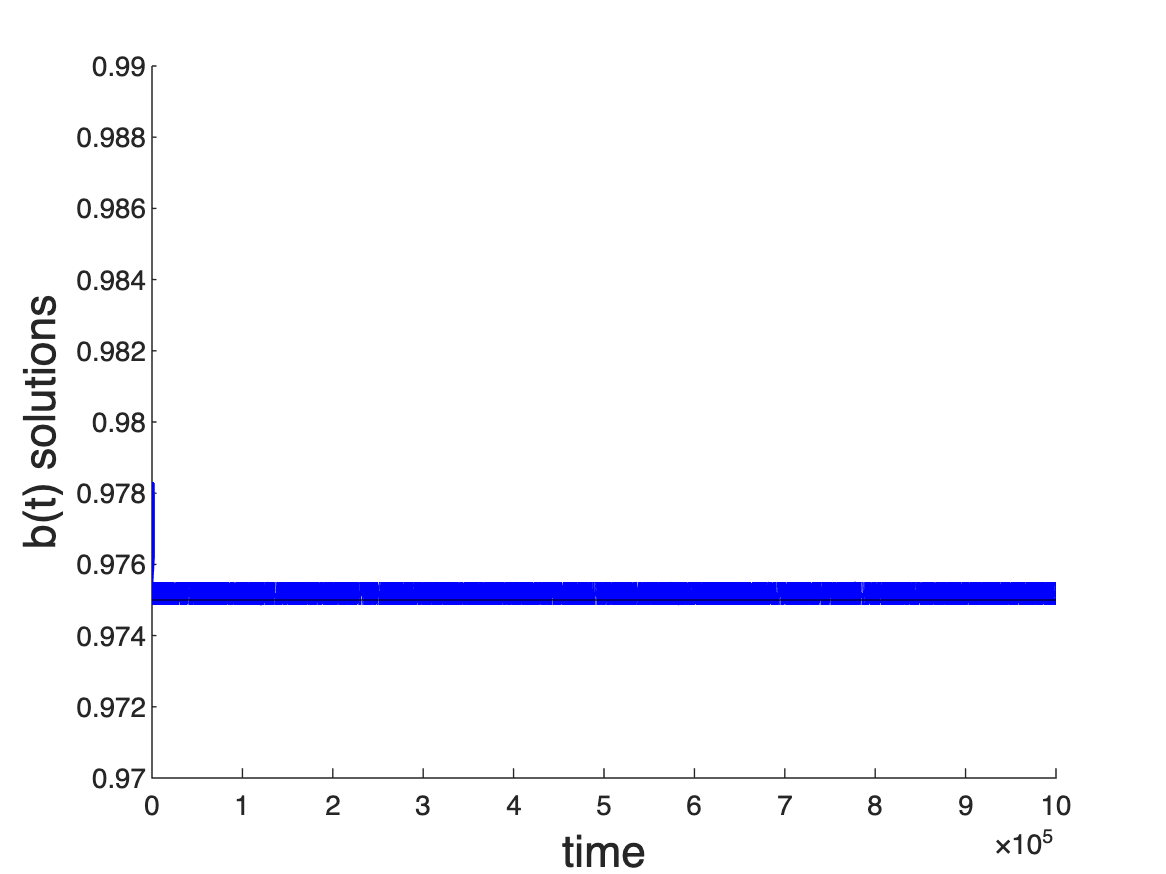

figure 
hold on
% %CHANGE LIMITS AS NEEDED
%ylim([0.985 0.99])
ylim([0.97 0.99])
plot(tx,exsolx(:,2),'b-','linewidth',2)
xlabel('time','FontSize',16);
ylabel('b(t) solutions','FontSize',16)
format long 
str = sprintf("Solution trajectory (%d, %d)", y0(1), y0(2));
%CHANGE SOLUTION: BOTTOM 0.9752, TOP 0.9828
%sol = 0.9828;
sol = 0.975;
yline(sol, 'k', 'FontSize',16)

% yline(0.9774, 'k', 'FontSize',16)

[pks,locs] = findpeaks(exsolx(:,2),tx);
[pks_min, locs_min] = findpeaks(-exsolx(:,2),tx)

pks_min =   -0.977319662112407
  -0.977334730411896
  -0.976959286133900
  -0.977181195334323
  -0.977280303268009
  -0.977139235510550
  -0.976330237160618
  -0.976907634307430
  -0.976933884640779
  -0.976467236931770


locs_min = 1.0e+05 *

   0.000033333063653
   0.000066666127307
   0.000113837464632
   0.000144266437445
   0.000174695410257
   0.000213971172743
   0.000257727249896
   0.000285420396312
   0.000313113542728
   0.000351541046126


%SET CUTOFF
cutoff = 30;
pks = pks([cutoff:end]);
locs = locs([cutoff:end]);
%sol = 0.9888
pks_min = pks_min([cutoff:end]);
locs_min = locs_min([cutoff:end]);

figure
hold on
%CHANGE BELOW
ylim([0.9855 0.9857]);
%ylim([0.9875 0.99]);

clear fit
%fit to exponetntial
f = fit(locs,pks,'exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.9753  (0.9753, 0.9753)
       b =   6.249e-15  (-1.051e-12, 1.063e-12)

f_min = fit(locs_min, -pks_min, 'exp1')

f_min =      General model Exp1:
     f_min(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.9751  (0.9751, 0.9751)
       b =  -4.333e-15  (-1.013e-12, 1.004e-12)

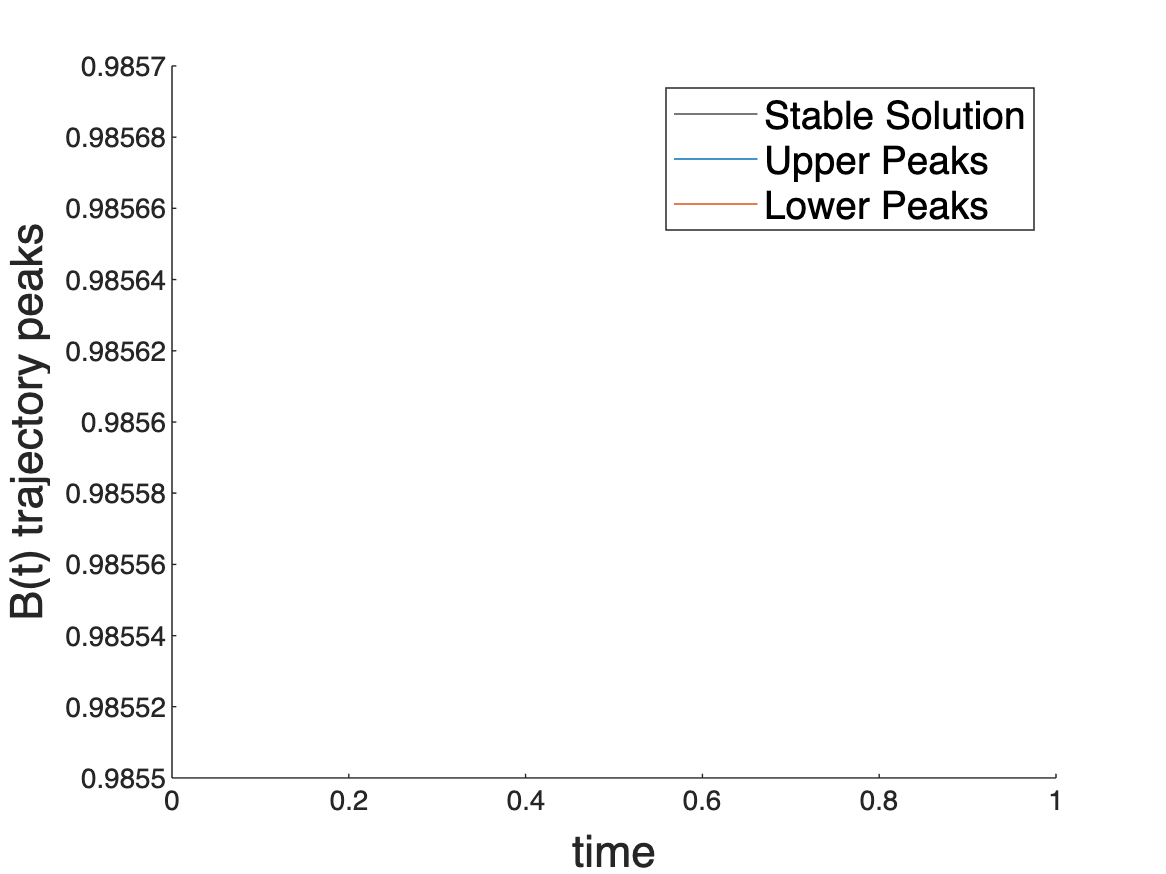

%plot(f,locs, pks)
%plot(f_min, locs_min, -pks_min)
%CHANE BELOW
yline(sol, 'k', 'FontSize',16)
plot(locs, pks)
plot(locs_min, -pks_min)
xlabel('time', 'FontSize',16);
ylabel('B(t) trajectory peaks', 'FontSize',16)
%legend('Upper Peaks', 'Upper Curve Fit', 'Lower Peaks', 'Lower Curve Fit', 'Stable Solution','FontSize',14, 'Location','southeast')
% plot(locs,pks)
% plot(locs_min, -pks_min)
legend('Stable Solution','Upper Peaks','Lower Peaks','FontSize',14)


syms x;
a =       0.9753;
b =  -2.248e-13;
equation = a*exp(b*x) == sol;

% ADJUST EQ ABOVE
converges_upper = vpasolve(equation,x)

$$converges\_upper = 1368527491.6466716855868799273199$$


syms x;
 a = 0.9751;
b =   1.784e-13 ;
clear equation
equation = a*exp(b*x) == sol;
converges_lower = vpasolve(equation,x)

$$converges\_lower = -574881408.21830129667278550531615$$